close("all"); clear; clc;

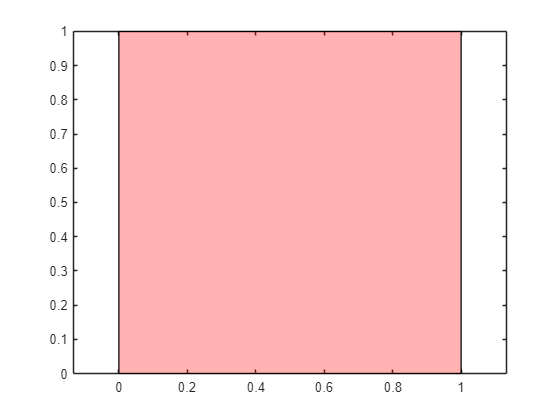

fig = figure();
axe = axes(fig);
z = zonotope2d(eye(2));
z.plot();
axis(axe,"equal");
box(axe,"on");

clear;

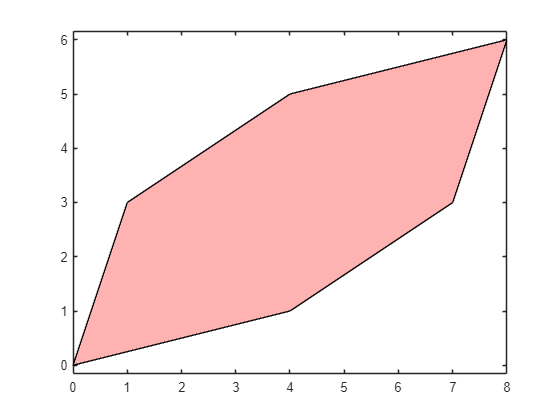

fig = figure();
axe = axes(fig);
z = zonotope2d([[4;1],[3;2],[1;3]]);
z.plot();
axis(axe,"equal");
box(axe,"on");

clear;

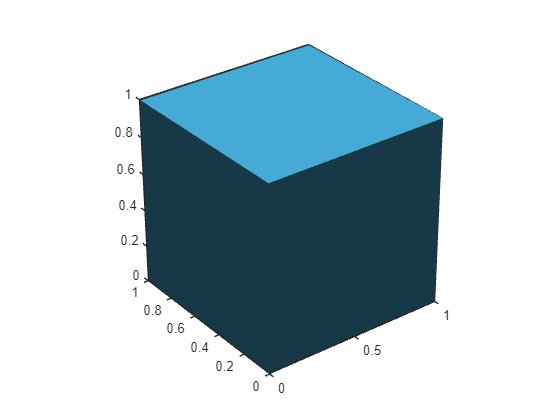

fig = figure();
axe = axes(fig);
z = zonotope3d(eye(3));
z.plot();

clear;

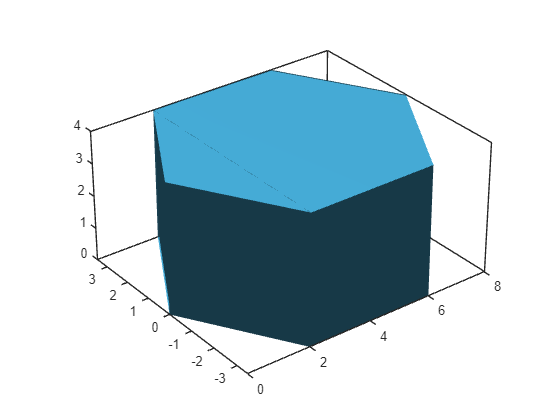

fig = figure();
axe = axes(fig);
U = 2.*[
    1,sqrt(3),0;
    1,-sqrt(3),0;
    2,0,0;
    0,0,2
    ].';
z = zonotope3d(U);
z.plot();

clear;

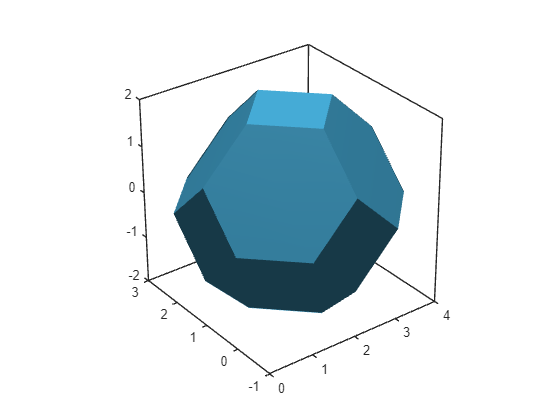

fig = figure();
axe = axes(fig);
U = [
    1,1,0;
    1,-1,0;
    1,0,1;
    1,0,-1;
    0,1,1;
    0,1,-1
    ].';
z = zonotope3d(U);
P = z.generate();
z.plot();

clear;

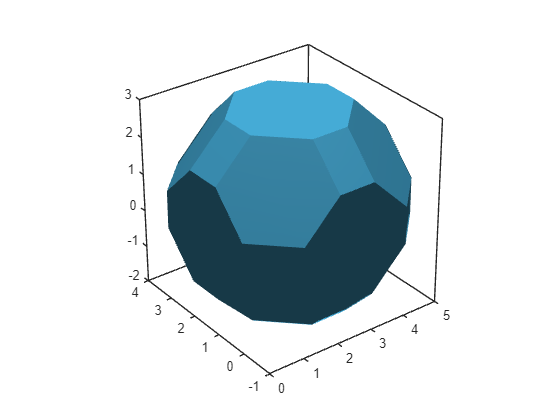

fig = figure();
axe = axes(fig);

za = zonotope3d(eye(3));

Ub = [
    1,sqrt(3),0;
    1,-sqrt(3),0;
    2,0,0;
    0,0,2
    ].';

zb = zonotope3d(Ub);

Uc = [
    1,1,0;
    1,-1,0;
    1,0,1;
    1,0,-1;
    0,1,1;
    0,1,-1
    ].';

zc = zonotope3d(Uc);
z = za + zc;
z.plot();